# Datasets y visualizacion

## Importar con readtable y readmatrix

%readmatrix
area_mm=readmatrix("../../ClonRepositorioAldo/Utils4SP/Datasets/areaMM.txt",'Delimiter','   ')

area_mm =   340.4277  324.3750  308.9114  293.6813  277.8073  261.0772  245.9019  232.8705  218.6999  203.1390  189.3382  176.6128  169.5532  168.8775  172.0049  174.4247  178.4295  183.9891  193.8382  206.2434  219.7135  234.3422  248.6808  263.1539  276.9246  293.0711  308.6514  324.5290  339.1647  348.7149  354.1932  356.6855  356.3495  354.7398  355.8347  358.5429  363.1208  370.1026  377.4434  387.1900  396.7827  403.9608  411.5069  420.4716  429.3214  439.3651  448.8747  459.0157  469.0630  478.9387



%readtable
PSD_bands=readtable("../../ClonRepositorioAldo/Utils4SP/Datasets/2021.10.04_IntensidadBobinas.xlsx")

PSD_bands = 630×13 table
    Dist_cm_    PSD_B1      PSD_B2        PSD_B3       PSD_B4       PSD_B5      PSD_B6      PSD_B7       PSD_B8       PSD_B9       PSD_B10      PSD_B11     PSD_Base 
    ________    _______    _________    __________    _________    _________    _______    _________    _________    _________    _________    _________    _________

      0.5       0.54799     0.012948     0.0051533    0.0046358     0.020502     1.1388     0.010652    0.0029874    0.0060306    0.0044177    0.0027482     0.008748
      0.5       0.50418    0.00171

## Funcion custom de Import File

%Pasa sonsa cassini
Cassini=importfile_Cassini('../../ClonRepositorioAldo/Utils4SP/Datasets/05358_mrdcd_sdfgmc_krtp_1s.asc',88,3000);

## Importar audio

[buho, fs_buho]=audioread("../../ClonRepositorioAldo/Utils4SP/Datasets/Owl.wav");
%escuchar
%sound(buho,fs_buho)


## Datastore

% %Le indicamos que una carpeta es un DataStore
% 
% ds=datastore("../../ClonRepositorioAldo/Utils4SP/Datasets/AtmosferaLogger_V2/");
% ds.VariableNames=["Fecha" "Hora" "Pres_kpa" "Temp_C" "Hum_perc" "Bat_V" ];
% ds.TextscanFormats=["%s" "%s" "%f" "%f" "%f" "%f"]
% 
% %leer todas las entradas
% atmosfera=readall(ds)
% %Parche por si la tabla ya se importo
% %atmosfera.Properties.VariableNames=["Fecha" "Hora" "Pres_kpa" "Temp_C" "Hum_perc" "Bat_V" ]


## Primeras lecturas Atmosfericas

ds=datastore("../../ClonRepositorioAldo/Utils4SP/Datasets/AtmosferaLogger/");
ds.VariableNames=["Fecha" "Hora" "Pres_kpa" "Temp_C" "Hum_perc"];
ds.TextscanFormats=["%s" "%s" "%f" "%f" "%f"]

ds =   TabularTextDatastore with properties:

                      Files: {
                             ' .../ClonRepositorioAldo/Utils4SP/Datasets/AtmosferaLogger/210425.txt';
                             ' .../ClonRepositorioAldo/Utils4SP/Datasets/AtmosferaLogger/210426.TXT';
                             ' .../ClonRepositorioAldo/Utils4SP/Datasets/AtmosferaLogger/210427.TXT'
                              ... and 35 more
                             }
                    Folders: {
                             ' .../Desktop/ClonRepositorioAldo/Utils4SP/Datasets/AtmosferaLogger'
                             }
               FileEncoding: 'UTF-8'
   AlternateFileSystemRoots: {}
         VariableNamingRule: 'modify'
          ReadVariableNames: false
              VariableNames: {'Fecha', 'Hora', 'Pres_kpa' ... and 2 more}
             DatetimeLocale: en_US

  Text Format Properties:
      

atmosfera=readall(ds)

atmosfera = 546110×5 table
      Fecha           Hora        Pres_kpa    Temp_C    Hum_perc
    __________    ____________    ________    ______    ________

    {'210425'}    {'21:03:51'}     78.05      28.79      33.52  
    {'210425'}    {'21:03:56'}     78.05      29.12      33.12  
    {'210425'}    {'21:04:01'}     78.05      29.16      33.09  
    {'210425'}    {'21:04:06'}     78.05       29.2      36.58  
    {'210425'}    {'21:04:11'}     78.05       29.3      35.68  
    {'210425'}    {'21:04:16'}     78.05      29.37      34.48  
    {'210425'}    {'21:04:22'}     78.05      29.43      33.99  
    {'210425'}    {'21:04:27'}     78.05       29.5         34  
    {'210425'}    {'21:04:32'}     78.05      29.57      34.21  
    {'210425'}    {'21:04:37'}     78.05      29.63      33.81  
    {'210425'}    {'21

## Corrigiendo

%solo si importa fecha y hora en dos columnas 
atmosfera.Datetime=string(atmosfera.Fecha)+" "+string(atmosfera.Hora);
% Pasar de texto a hora
atmosfera.Datetime=datetime(atmosfera.Datetime,"Format","yyyyMMdd HH:mm:ss")

atmosfera = 546110×6 table
      Fecha           Hora        Pres_kpa    Temp_C    Hum_perc        Datetime     
    __________    ____________    ________    ______    ________    _________________

    {'210425'}    {'21:03:51'}     78.05      28.79      33.52      20210425 21:03:51
    {'210425'}    {'21:03:56'}     78.05      29.12      33.12      20210425 21:03:56
    {'210425'}    {'21:04:01'}     78.05      29.16      33.09      20210425 21:04:01
    {'210425'}    {'21:04:06'}     78.05       29.2      36.58      20210425 21:04:06
    {'210425'}    {'21:04:11'}     78.05       29.3      35.68      20210425 21:04:11
    {'210425'}    {'21:04:16'}     78.05      29.37      34.48      20210425 21:04:16
    {'210425'}    {'21:04:22'}     78.05      29.43      33.99      20210425 21:

## Seleccion de Datos

Tomaremos los datos entre el 18 al 26 de mayo a las 6AM


%Puntos en el tiempo donde inicia y finaliza
T1=datetime(2021,05,18,6,0,0)

T1 = datetime
   18-May-2021 06:00:00


T2=datetime(2021,05,26,6,0,0)

T2 = datetime
   26-May-2021 06:00:00




%% Creando datos de seleccion de datos
 index= atmosfera.Datetime>T1 & atmosfera.Datetime<T2;
% Probando
% index = T1<atmosfera.Datetime<T2
atmosfera_part=atmosfera(index,:);


## Limpieza de NAN's

sum(ismissing(atmosfera_part))

ans =      0     0     0    11    61     0


summary(atmosfera_part)

Variables:

    Fecha: 137522×1 cell array of character vectors

    Hora: 137522×1 cell array of character vectors

    Pres_kpa: 137522×1 double

        Values:

            Min        77.55  
            Median     78.06  
            Max        78.46  

    Temp_C: 137522×1 double

        Values:

            Min             13.38  
            Median          21.01  
            Max             100    
            NumMissing      11     

    Hum_perc: 137522×1 double

        Values:

            Min             15.27  
            Median          50.16  
            Max             99.97  
            NumMissing      61     

    Datetime: 137522×1 datetime

        Values:

            Min       20210518 06:00:03
            Median    20210522 05:59:48
            Max       20210526 05:59:55




%Remover filas con NAN's
Atmosfera_NoNANs=rmmissing(atmosfera_part);
summary(Atmosfera_NoNANs)

Variables:

    Fecha: 137450×1 cell array of character vectors

    Hora: 137450×1 cell array of character vectors

    Pres_kpa: 137450×1 double

        Values:

            Min        77.55  
            Median     78.06  
            Max        78.46  

    Temp_C: 137450×1 double

        Values:

            Min        13.38  
            Median     21.01  
            Max        46.86  

    Hum_perc: 137450×1 double

        Values:

            Min         15.27 
            Median     50.155 
            Max         99.97 

    Datetime: 137450×1 datetime

        Values:

            Min       20210518 06:00:03
            Median    20210522 05:57:17
            Max       20210526 05:59:55



## Ploteo exploratorio

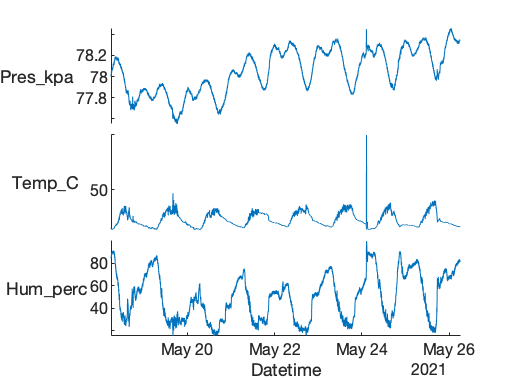

figure
stackedplot(atmosfera_part,"XVariable","Datetime")

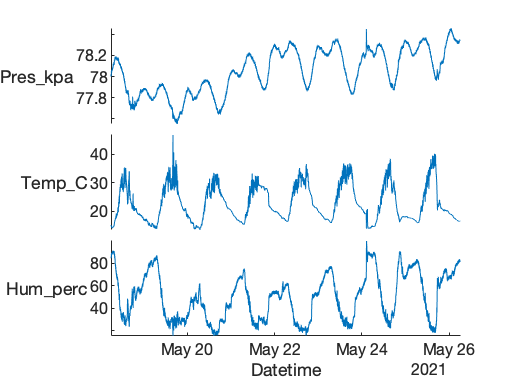


figure
stackedplot(Atmosfera_NoNANs,"XVariable","Datetime")

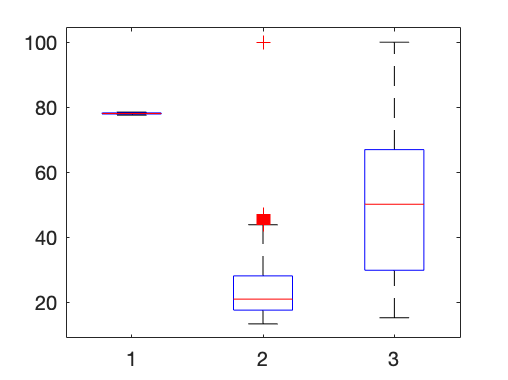


figure
boxplot(atmosfera_part{:,["Pres_kpa" "Temp_C" "Hum_perc" ]})

## 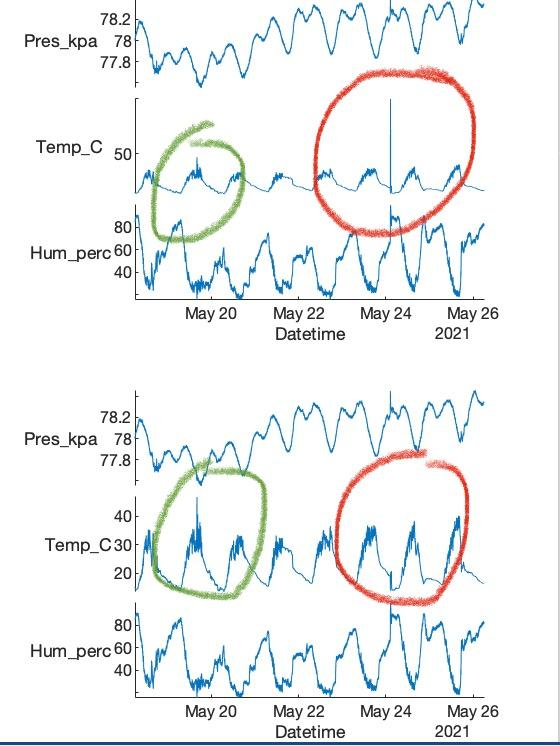

## Con NaNs/ Sin NaNs  (cambios a simple vista)

## Histograma

figure 
histogram(atmosfera_part.Hum_perc)


figure 
histogram(atmosfera_part.Hum_perc,"BinWidth",1)



figure 
histogram(atmosfera_part.Hum_perc,"BinWidth",15)

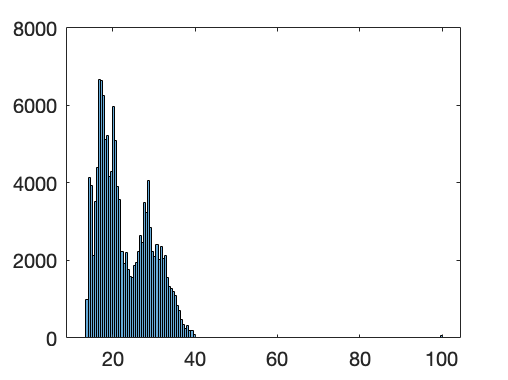



figure 
histogram(atmosfera_part.Temp_C,"BinWidth",0.5)

## Dispersion

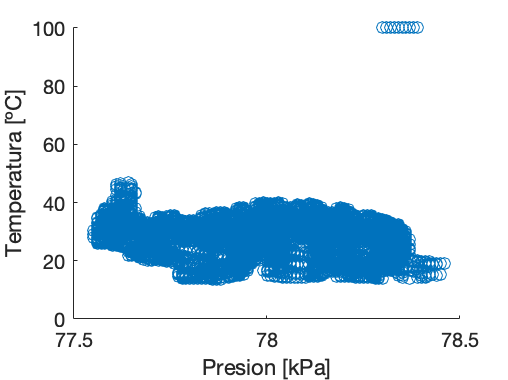

scatter(atmosfera_part.Pres_kpa,atmosfera_part.Temp_C)
xlabel("Presion [kPa]")
ylabel("Temperatura [ºC]")

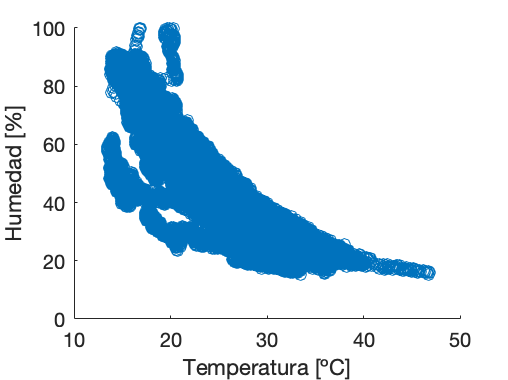


scatter(atmosfera_part.Temp_C,atmosfera_part.Hum_perc)
xlabel("Temperatura [ºC]")
ylabel("Humedad [%]")

## Plot Matrix

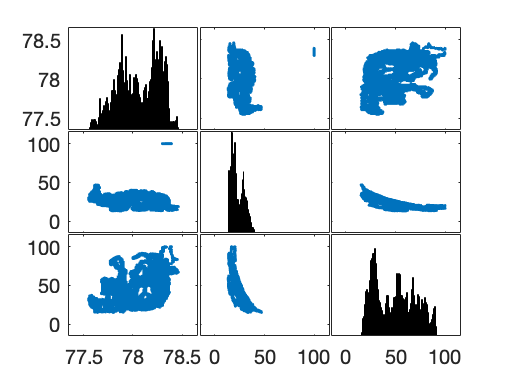

figure
plotmatrix(atmosfera_part{:,["Pres_kpa" "Temp_C" "Hum_perc"]})

## TiledLayout

%tiledlayout("flow")
tiledlayout(3,1)
nexttile
plot(atmosfera_part.Datetime, atmosfera_part.Pres_kpa)
ylabel("Presion [kPa] \sigma")
%xlabel("Fecha ")
title("Parametros atmosfericos en la casa de Aldo")
set(gca,"xtick",[])

nexttile
plot(atmosfera_part.Datetime, atmosfera_part.Temp_C)
ylabel("Temperatura [ºC] \sigma")
%xlabel("Fecha ")
set(gca,"xtick",[])

nexttile
plot(atmosfera_part.Datetime, atmosfera_part.Hum_perc)
ylabel("Humedad [%] \sigma")
xlabel("Fecha ")

## Agrupacion y orden

% Vamos a darle categorias a temperatura
% Fronteras de las categorias
edges=[-30 15 20 55]

edges =    -30    15    20    55


% categorias
categorias=["Frio" "Templado" "Caliente"]

categorias = 1×3 string array
    "Frio"    "Templado"    "Caliente"


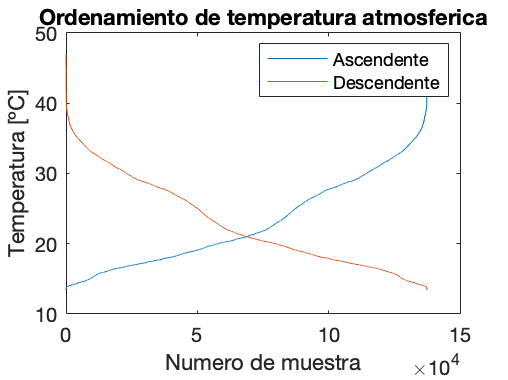

% Se clasificaron las temperaturas 
temp_cats=discretize(Atmosfera_NoNANs.Temp_C,edges,"categorical",categorias);
% Se agrego a la tabla original
Atmosfera_NoNANs.temp_cats=temp_cats;
% Se ordenan (funcion sort)
temp_Descend=sort(Atmosfera_NoNANs.Temp_C,"descend");
temp_Ascend=sort(Atmosfera_NoNANs.Temp_C,"ascend");

figure
plot([temp_Ascend temp_Descend ])
ylabel("Temperatura [ºC]")
xlabel("Numero de muestra")
legend("Ascendente","Descendente")
title("Ordenamiento de temperatura atmosferica")

## G scatter y pareto chart

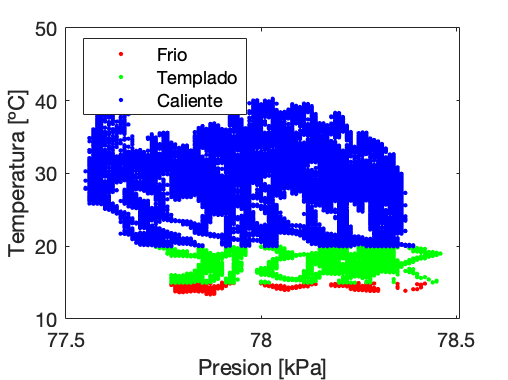

%sirve para comparar datos o variables que no apareceria en los ejes de las
%variables 
figure 
gscatter(Atmosfera_NoNANs.Pres_kpa,Atmosfera_NoNANs.Temp_C,Atmosfera_NoNANs.temp_cats)
xlabel("Presion [kPa]")
ylabel("Temperatura [ºC]")

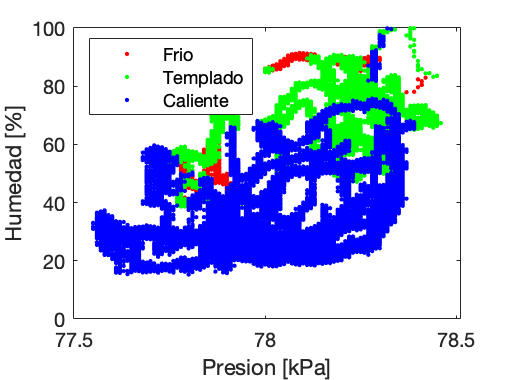


%%buen ejemplo, se ve la temperatura, humedad y presion en la misma grafica
figure 
gscatter(Atmosfera_NoNANs.Pres_kpa,Atmosfera_NoNANs.Hum_perc,Atmosfera_NoNANs.temp_cats)
xlabel("Presion [kPa]")
ylabel("Humedad [%]")

## Pareto

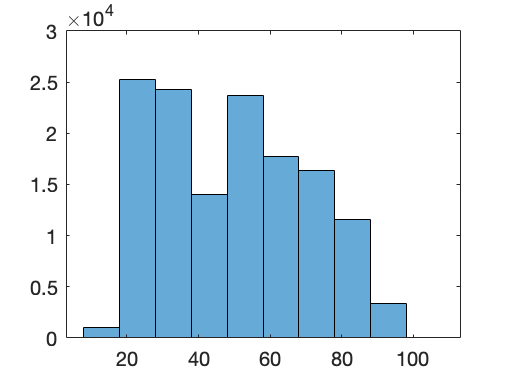

h=histogram(Atmosfera_NoNANs.Hum_perc,10);

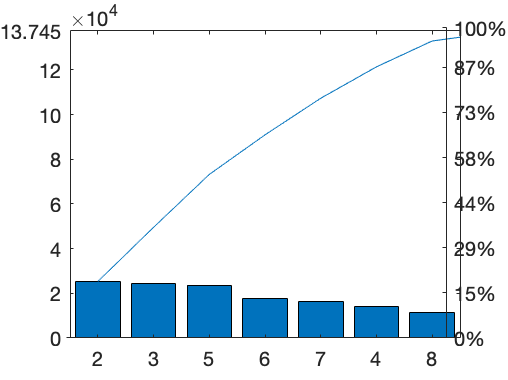

cuentas=h.BinCounts;

figure
pareto(cuentas)